# B3シミュレーション

## 送信側

clear;
clc;

%データレートよりもサンプリング周波数の方が十分大きくなければならない
Fs = 10000 %サンプリング周波数[Hz]

Fs = 10000

Ts = 1/Fs  %サンプリング周期[s]

Ts = 1.0000e-04

Fd = 10    %データレート[Hz]

Fd = 10

Td = 1/Fd  %データの周期（ナイキスト周期）[s]

Td = 0.1000

Fc = 100   %搬送波周波数[Hz]

Fc = 100

A  = 1     %振幅

A = 1

TXD = [0 0 1 1 0 0 1 0 0 1 0]  %送信データ

TXD =      0     0     1     1     0     0     1     0     0     1     0


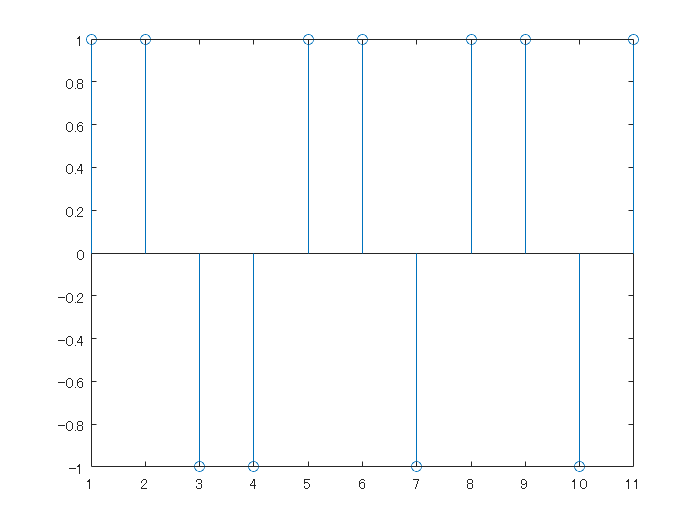

t  = 0:Ts:(numel(TXD)-1)*Td;   %離散時間[s]

%信号空間ダイアグラムへのマッピング
BPSK(TXD==0) = A;
BPSK(TXD==1) = -A;
stem(BPSK)

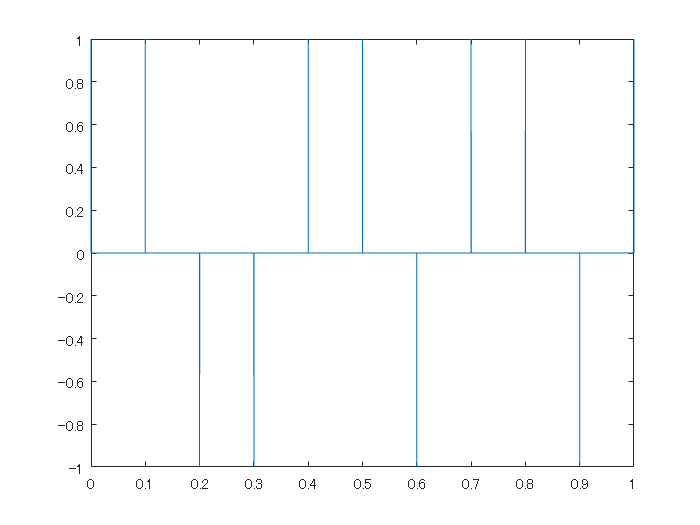


%インパルス列作成
i = 1;
impulse = zeros(1,numel(t));
for data = BPSK
    impulse(i) = data;
    i = i + Fs/Fd;
end
plot(t,impulse);

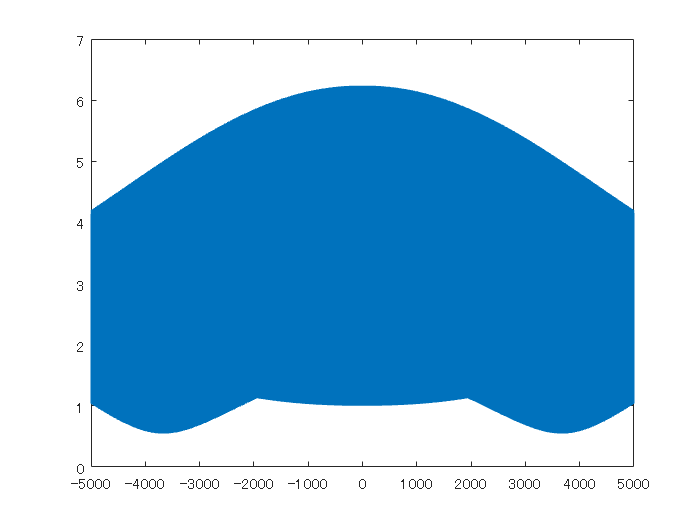

f_impulse = linspace(-Fs/2,Fs/2,numel(t));
impulse_fft = fft(impulse);
plot(f_impulse,abs(fftshift(impulse_fft)));

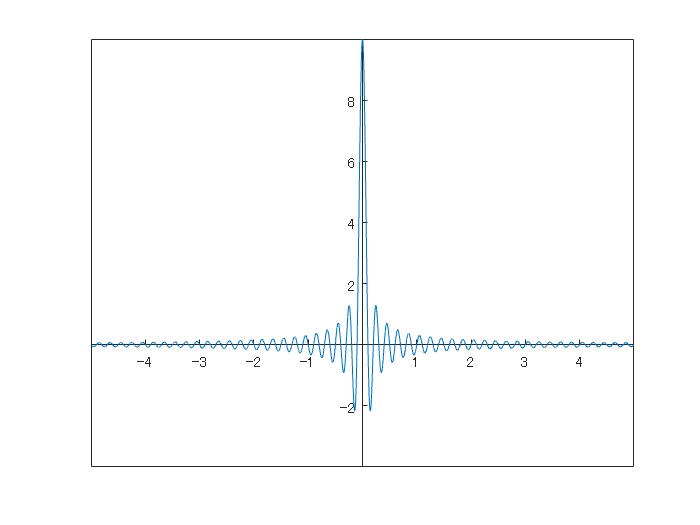


%フィルタのインパルス応答を計算
k = 50;%フィルタインパルス応答の打ち切り時間調整
tf = -Td*k:Ts:Td*k-Ts; %フィルタインパルス応答の時間列
h = (1/Td).*sinc(tf/Td);

plot(tf,h);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

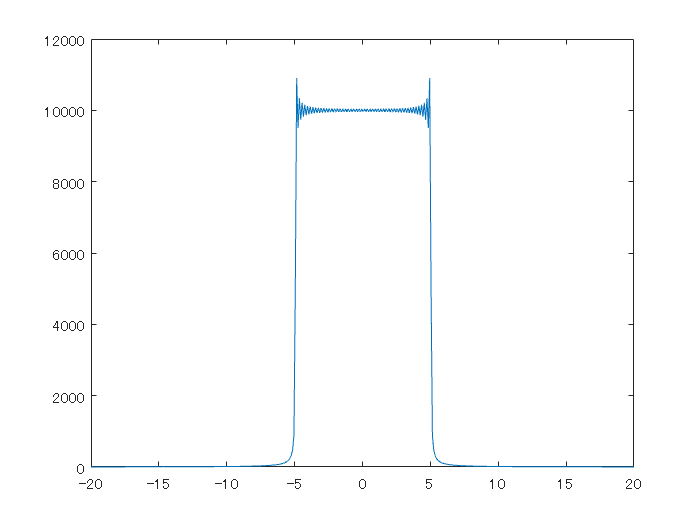

h_fft = fft(h);

f_h = linspace(-Fs/2,Fs/2,numel(tf));
plot(f_h,abs(fftshift(h_fft)));
xlim([-2/Td 2/Td]);

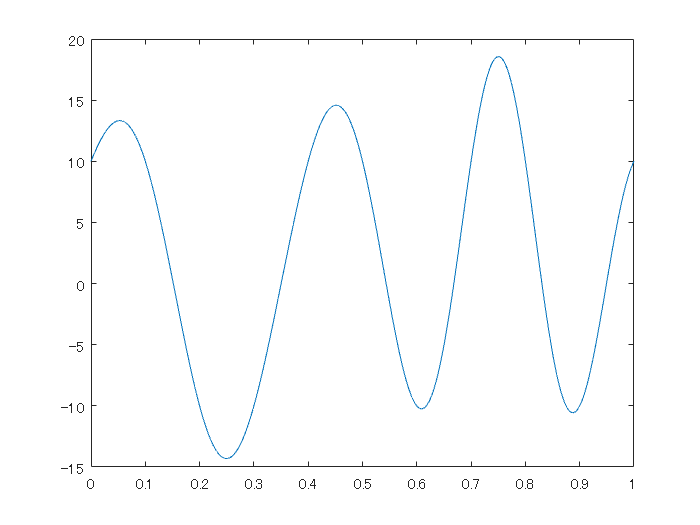


%インパルス列をフィルタに通過させる
impulse_LPF = conv(impulse,h);
delay = numel(h)/2; %フィルタの遅延量
impulse_LPF(1:delay) = []; %先頭の遅延分を削除
impulse_LPF = impulse_LPF(1:numel(t)); %後ろの遅延分を削除
plot(t,impulse_LPF);

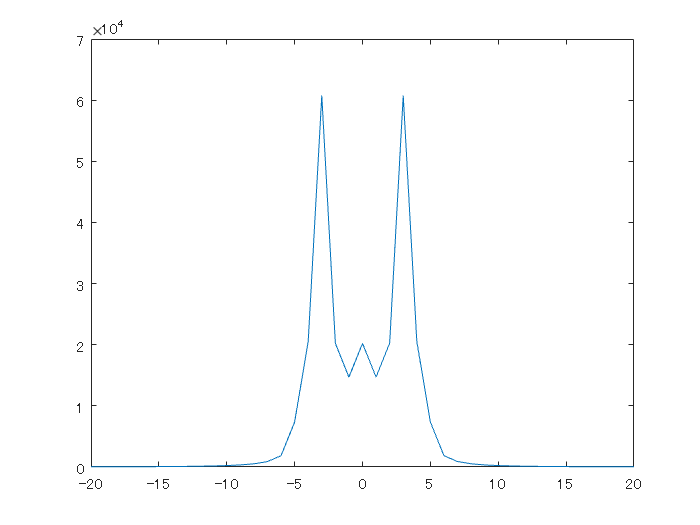


f = linspace(-Fs/2,Fs/2,numel(t));
plot(f,abs(fftshift(fft(impulse_LPF))));
xlim([-2/Td 2/Td]);

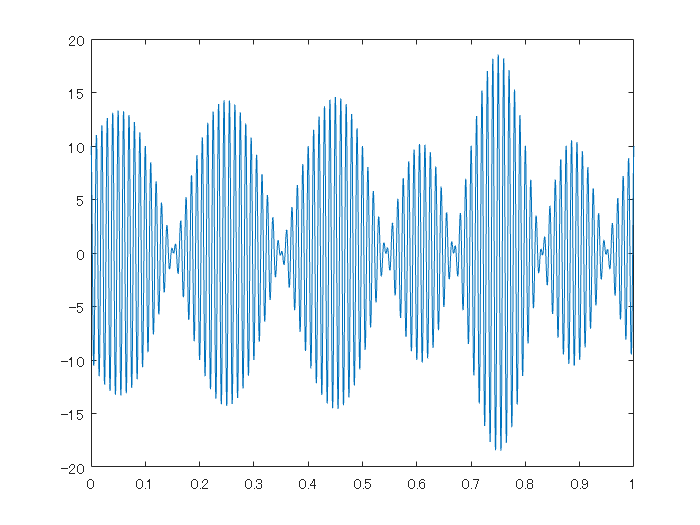


%インパルス列を搬送波に乗せる
carrier = cos(2*pi*Fc*t); %搬送波
s = impulse_LPF.*carrier;
plot(t,s);

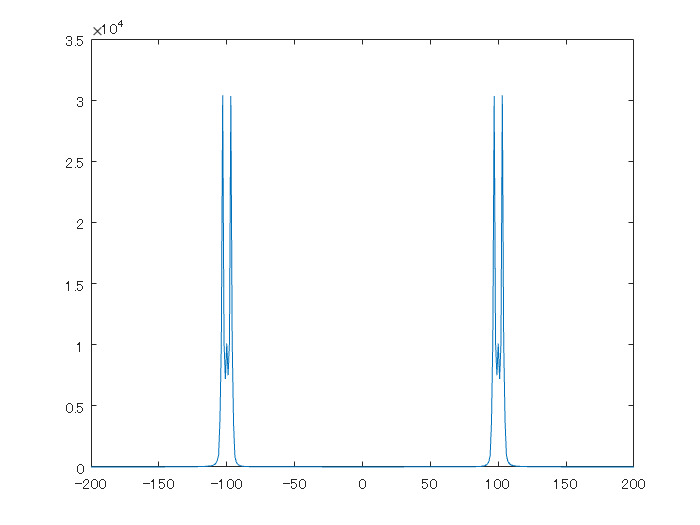

plot(f,abs(fftshift(fft(s))));
xlim([-2*Fc 2*Fc]);

## ノイズ付加

noisePower = 10000; %ノイズ電力
r = s + normrnd(0,sqrt(noisePower),[1,numel(s)]);

## 受信側

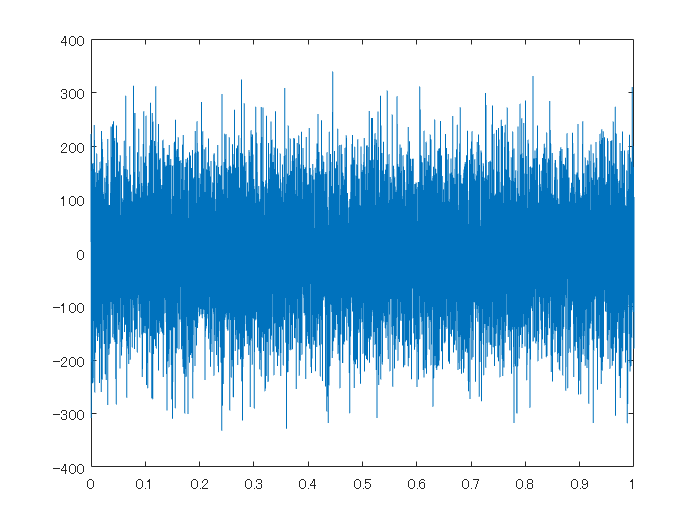

plot(t,r);

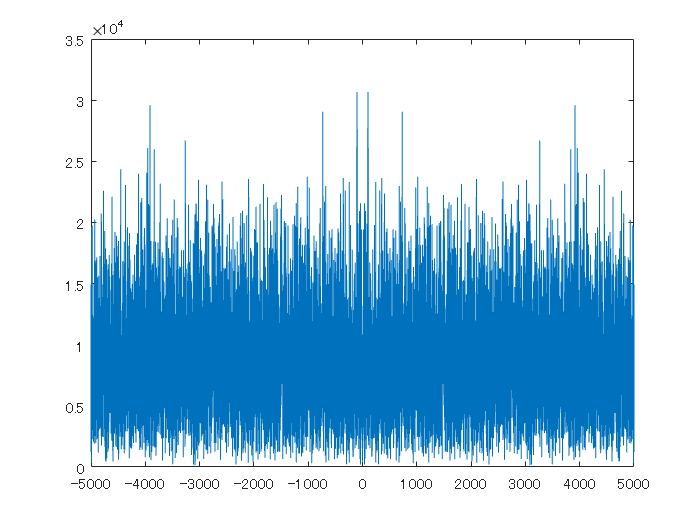

plot(f,abs(fftshift(fft(r))));

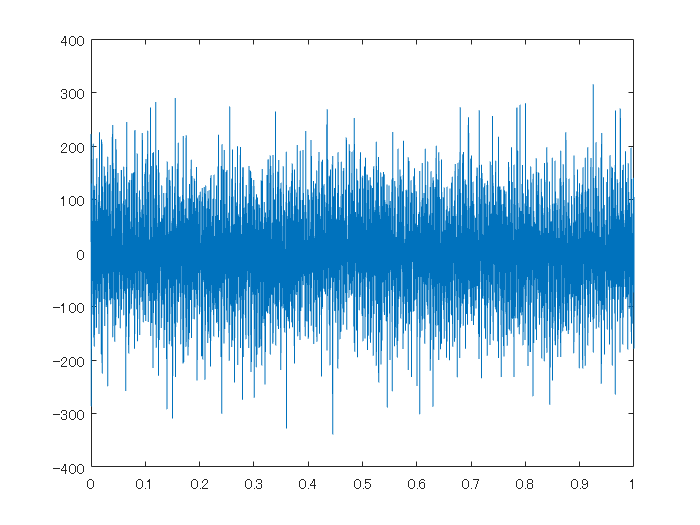

rd = r.*carrier; %受信波と基準信号と掛ける
plot(t,rd);

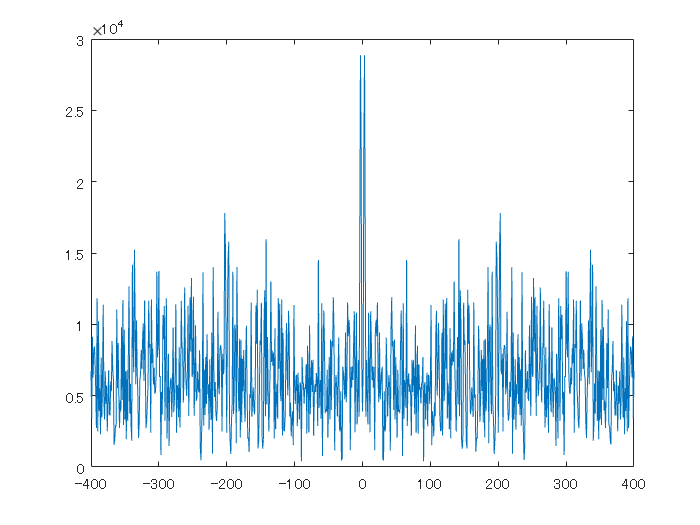

plot(f,abs(fftshift(fft(rd))));
xlim([-4*Fc 4*Fc]);

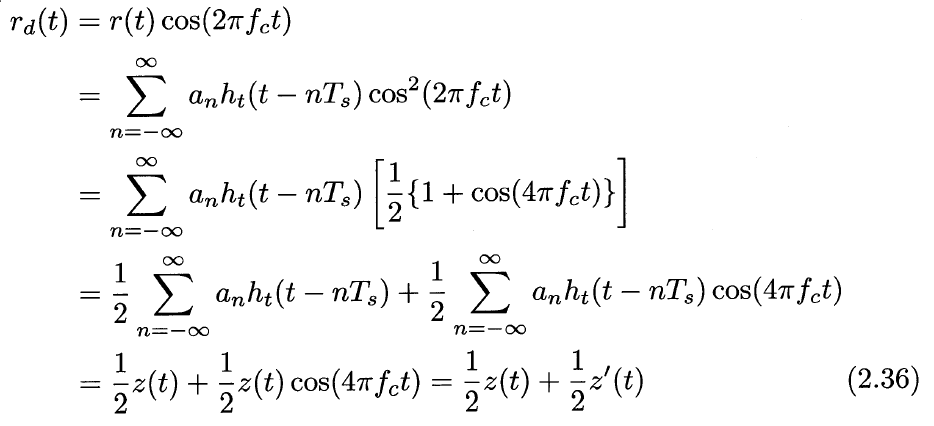

%高調波を除去
%フィルタのインパルス応答を計算（送信側のLPFと同じ）
k = 50; %フィルタインパルス応答の打ち切り時間調整
tf = -k*Td:Ts:Td*k-Ts;        %フィルタインパルス応答の時間列
h = (1/Td).*sinc(tf/Td);
plot(tf,h);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

f_h = linspace(-Fs/2,Fs/2,numel(tf));
plot(f_h,abs(fftshift(fft(h))));
xlim([-2/Td 2/Td]);

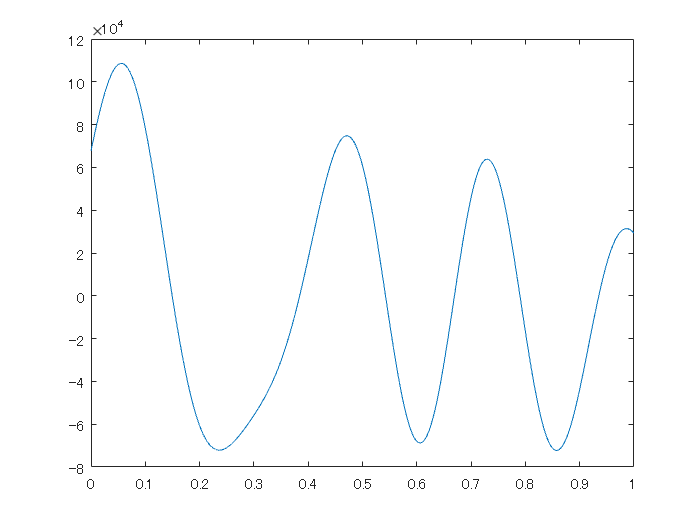


%rdをフィルタに通過させる
rd_LPF = conv(rd,h);
delay = numel(h)/2;             %フィルタの遅延量
rd_LPF(1:delay) = [];           %先頭の遅延分を削除
rd_LPF = rd_LPF(1:numel(t));    %後ろの遅延分を削除
plot(t,rd_LPF);

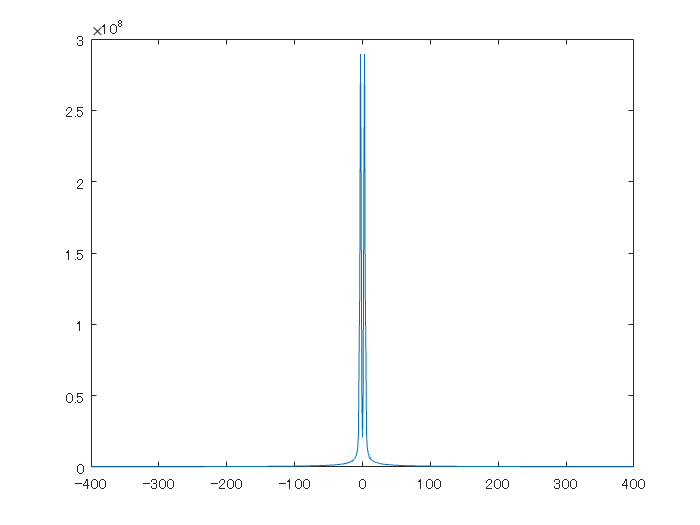

plot(f,abs(fftshift(fft(rd_LPF))));
xlim([-4*Fc 4*Fc]);


%ビット判定（符号変換）
RXD = zeros(1,numel(TXD));
j = 1;
for i = 1:numel(TXD)
    if  rd_LPF(j)>0
        RXD(i) = 0;
    else
        RXD(i) = 1;
    end
    j = j + Fs/Fd;
end

RXD %受信ディジタル信号

RXD =      0     0     1     1     0     0     1     0     1     1     0
